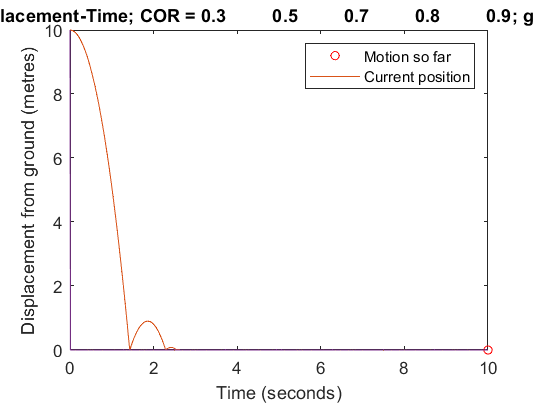

% this software models the motion of a ball as it is free falling
% Assumptions:
    % there are no (neglegible) resistive forces
    % the cor, between the ball ground, is constant for each collision

%
% fixed constants
g = -9.81; % (metres per second, squared) acceleration due to gravity
end_time = 10; % (seconds) time to stop the motion
t_step = 0.01; % (seconds) the interval between each time value

%
% user-inputted constants
initial_height = input("What initial height would you like?\n"); % (metres) this is the height at time = 0
initial_velocity = input("What initial velocity would you like?\n"); % (metres per second) this is the velocity at time = 0
num_graphs = input("How many graphs would you like to display?\n");
if num_graphs <= 0
    return;
end
for i = 1:num_graphs
    cor(i) = input(strcat("What coefficient of restitution would you like for graph no. ",num2str(i),"?\n")); % (between 0 and 1) this is the coefficient of restitution
end

%
% main code
tArray = []; % (seconds) this is an array containing all the time values since the start of the motion
sArray = []; % (metres) this is an array containing all the displacement values since the start of the motion
vArray = []; % (metres per second) this is an array containing all the velocity values since the start of the motion

v = initial_velocity; % (metres per second) the velocity at each loop cycle
s = initial_height; % (metres) the displacement at each loop cycle

for i = 1:num_graphs
    tArray(i, 1) = 0;
    sArray(i, 1) = s;
    vArray(i, 1) = v;
end

% runs the loop for every time interval in the range
for i = 1:num_graphs
    count = 2; % this is a count, storing the loop count as an integer
    for t = t_step:t_step:end_time
    
        % finds the next velocity and displacement
        v = vArray(i, count - 1) + g*t_step;
        s = s + t_step * ((vArray(i, count -1) + v) / 2);
    
        % if the displacement is below the ground, BOUNCE!!!
        if s <= 0
            v = -cor(i) * v;
            s = 0;
        end
    
        % puts each of the values into its array, for this loop iteration
        tArray(i,count) = t;
        sArray(i,count) = s;
        vArray(i,count) = v;
    
        % plots the motion so far, then the ball

        plot(t, s, "r o","MarkerSize", 5)
        hold on;
        for j = 1:i
            plot(tArray(j, :), sArray(j, :))
        end

        hold off;
    
        axis([0 end_time 0 initial_height]);
        title(strcat("Displacement-Time; COR = ", num2str(cor), "; g = ", num2str(g)));
        xlabel("Time (seconds)");
        ylabel("Displacement from ground (metres)");
        legend("Motion so far", "Current position");
    
        %increments the count, then pauses for a period
        count = count + 1;
    end
end